1- Data Inject 

TestName="jan7";
% "jan11" "jan12" "feb27" "mar7" "mar16" "apr20"
TestFile=sprintf("%s_ana",TestName);

S = load_test(TestName,TestFile);

jan7_ana is Loaded (1/1)


2- Define the signal and sample it

TrialNum = 35;
TimeRange = [10 15];
ExpLabel = S.(AnaLabel).AnaPar.ExpTable.('Occ');
stim_freq = S.jan7_test.ExpPar.stim_freq;
FrameInd = ceil([stim_freq*TimeRange(1):stim_freq*TimeRange(2)]);

TrialLabel = sprintf("Trial_%d", TrialNum);
EMGFrames = S.(AnaLabel).(ExpLabel).(TrialLabel).BlankEMGFrames;




3- Define m-Wave templates

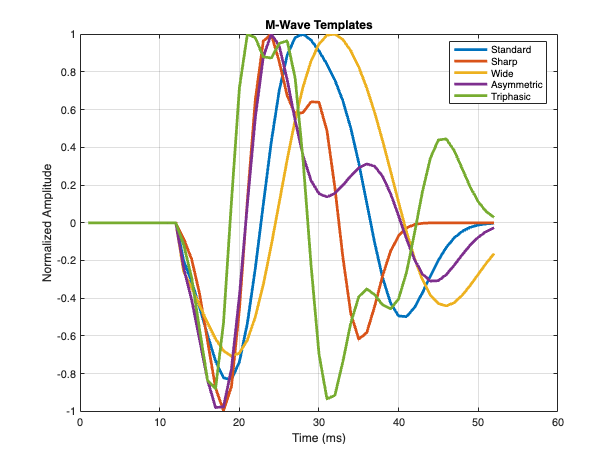

t = linspace(0, 1, 40);
template_std = 5*(t-0.25).*exp(-((t-0.25)/0.15).^2) - 3*(t-0.60).*exp(-((t-0.60)/0.15).^2);
template_sharp = 8*(t-0.20).*exp(-((t-0.20)/0.10).^2) - 5*(t-0.50).*exp(-((t-0.50)/0.10).^2);
template_wide = 4*(t-0.30).*exp(-((t-0.30)/0.20).^2) - 2.5*(t-0.70).*exp(-((t-0.70)/0.20).^2);
template_asym = 8*(t-0.20).*exp(-((t-0.20)/0.12).^2) - 2*(t-0.70).*exp(-((t-0.70)/0.15).^2);

% Template 5: Triphasic (complex with three phases)
template_tri = 6*(t-0.15).*exp(-((t-0.15)/0.08).^2) - 5*(t-0.40).*exp(-((t-0.40)/0.10).^2) + 2*(t-0.75).*exp(-((t-0.75)/0.12).^2);

zeros_prefix = zeros(1, 12);

templates = {[zeros_prefix, template_std/max(abs(template_std))], ...
             [zeros_prefix, template_sharp/max(abs(template_sharp))], ...
             [zeros_prefix, template_wide/max(abs(template_wide))], ...
             [zeros_prefix, template_asym/max(abs(template_asym))], ...
             [zeros_prefix, template_tri/max(abs(template_tri))]};
names = {'Standard', 'Sharp', 'Wide', 'Asymmetric', 'Triphasic'};
figure;
plot( templates{1}, 'LineWidth', 2.5); 
hold on;
plot(templates{2}, 'LineWidth', 2.5);
plot(templates{3}, 'LineWidth', 2.5);
plot(templates{4}, 'LineWidth', 2.5);
plot(templates{5}, 'LineWidth', 2.5);

xlabel('Time (ms)');
ylabel('Normalized Amplitude');
title('M-Wave Templates');
legend(names, 'Location', 'best');
grid on;

4- Apply Kalman Filters

TemplateNum=5;
opts.custom_template = templates{TemplateNum};
opts.process_noise = 0.05;
opts.meas_noise = 0.01;
[MWave, vEMG, ~] = FiltKalman(EMGFrames, 2000, opts);
    
vEMG_Kalman = vEMG(:, FrameInd);
MWave_Kalman = MWave(:, FrameInd);

Unfiltered = EMGFrames(:, FrameInd);


5- Plotting 

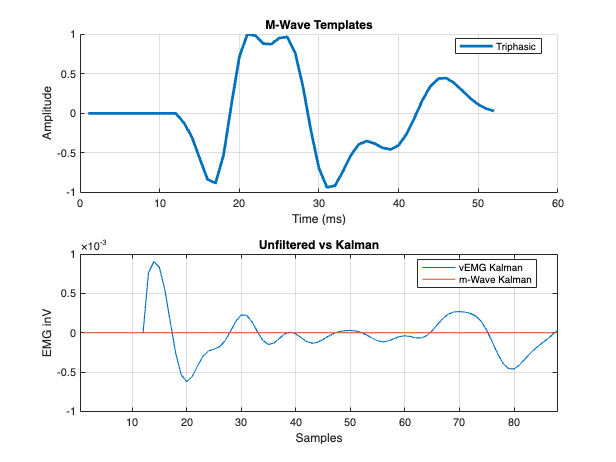

colors = lines(5);
time_axis = (1:length(Unfiltered)) / 2000 * 1000; % Convert to ms

% Plot 1: Templates

figure
subplot(2, 1, 1);
hold on;

plot (opts.custom_template, 'LineWidth', 2.5, 'DisplayName', names{TemplateNum});

xlabel('Time (ms)'); ylabel('Amplitude'); title('M-Wave Templates');
legend('Location', 'best', 'FontSize', 9); grid on;
Frame=1;
% Plot 2: Unfiltered Signal
subplot(2, 1, 2);
plot(vEMG_Kalman(:,Frame), 'LineWidth', 1 ,'DisplayName','vEMG Kalman');
hold on
plot(MWave_Kalman(:,Frame), 'LineWidth', 1 ,'DisplayName','m-Wave Kalman');
xlabel('Time (ms)'); ylabel('EMG (V)'); 
grid on; xlim([time_axis(1) time_axis(end)]);

xlabel('Samples'); ylabel('EMG inV'); title('Unfiltered vs Kalman');
legend('Location', 'best'); grid on;

6- Kalman filter function

function [MWaveFrames, vEMGFrames, filter_metrics] = FiltKalman(x_frames, varargin)
% Kalman filter for M-wave removal
% Usage: [MWave, vEMG, metrics] = FiltKalman(frames, fs, options)

% Parse inputs
if nargin < 1, error('Need x_frames'); end
fs = 2000;
options = struct();

if nargin >= 2
    if isstruct(varargin{1})
        options = varargin{1};
    else
        fs = varargin{1};
        if nargin >= 3 && isstruct(varargin{2})
            options = varargin{2};
        end
    end
end

% % Set defaults
% if ~isfield(options, 'template_length'), options.template_length = round(0.020 * fs); end
% if ~isfield(options, 'process_noise'), options.process_noise = 0.05; end
% if ~isfield(options, 'meas_noise'), options.meas_noise = 0.01; end

[frame_length, num_frames] = size(x_frames);
MWaveFrames = zeros(frame_length, num_frames);
vEMGFrames = zeros(frame_length, num_frames);

filter_metrics.amplitude_estimates = zeros(1, num_frames);
filter_metrics.posterior_variance = zeros(1, num_frames);
filter_metrics.innovation_rms = zeros(1, num_frames);
filter_metrics.kalman_gains = zeros(1, num_frames);

% Create or use custom template
if isfield(options, 'custom_template')
    mwave_template = options.custom_template(:);
else
    mwave_samples = options.template_length;
    t_mwave = linspace(0, 1, mwave_samples);
    t1 = 0.25; t2 = 0.60; sigma = 0.15;
    mwave_template = 5 * (t_mwave - t1) .* exp(-((t_mwave - t1)/sigma).^2) - ...
                     3 * (t_mwave - t2) .* exp(-((t_mwave - t2)/sigma).^2);
    mwave_template = mwave_template(:) / max(abs(mwave_template));
end

mwave_samples = length(mwave_template);

% Initialize Kalman filter
amplitude_estimate = 1.0;
variance_estimate = 0.1;
Q = options.process_noise;
R = options.meas_noise;

% Process each frame
for iFrame = 1:num_frames
    current_frame = x_frames(:, iFrame);
    current_length = length(current_frame);
    y_observed = current_frame(:);
    
    % Adjust template
    if current_length > mwave_samples
        template_segment = [mwave_template; zeros(current_length - mwave_samples, 1)];
    else
        template_segment = mwave_template(1:current_length);
    end
    
    % PREDICTION
    amplitude_pred = amplitude_estimate;
    variance_pred = variance_estimate + Q;
    
    % INNOVATION
    predicted_mwave = amplitude_pred * template_segment;
    innovation = y_observed - predicted_mwave;
    
    % KALMAN GAIN
    H_squared = sum(template_segment.^2);
    S = H_squared * variance_pred + R * current_length;
    K = (S > 1e-10) * variance_pred * sum(template_segment .* innovation) / max(S, 1e-10);
    
    % UPDATE
    amplitude_estimate = amplitude_pred + K;
    variance_estimate = (1 - K * H_squared / max(S, 1e-10)) * variance_pred;
    variance_estimate = max(min(variance_estimate, 1.0), 1e-6);
    amplitude_estimate = max(min(amplitude_estimate, 5.0), 0);
    
    % OUTPUT
    estimated_mwave_segment = amplitude_estimate * template_segment;
    vemg_segment = y_observed - estimated_mwave_segment;
    
    MWaveFrames(:, iFrame) = estimated_mwave_segment;
    vEMGFrames(:, iFrame) = vemg_segment;
    
    % METRICS
    filter_metrics.amplitude_estimates(iFrame) = amplitude_estimate;
    filter_metrics.posterior_variance(iFrame) = variance_estimate;
    filter_metrics.innovation_rms(iFrame) = rms(innovation);
    filter_metrics.kalman_gains(iFrame) = K;
end

% Clean up
MWaveFrames(isnan(MWaveFrames)) = 0;
MWaveFrames(isinf(MWaveFrames)) = 0;
vEMGFrames(isnan(vEMGFrames)) = 0;
vEMGFrames(isinf(vEMGFrames)) = 0;
end